**The simulations for the negative feedback model where mRNA inhibits its own production.**

**For Figure S1e and f.**

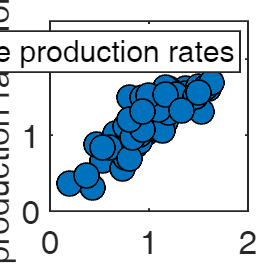

%%% Perturb mRNA production

bm=1;
a=rand(1,60)*2000;
b=3;

syms cm

kn_res=zeros(1,length(a));
cm_res=zeros(1,length(a));
for i=1:length(a)
    vdeg=bm*cm;
    vpro=a(i)/(cm+b);

    eq=vdeg==vpro;
    temp1=solve(eq,cm);
    temp2=double(temp1);
    temp3=temp2(temp2>0);

    cm_res(i)=poissrnd(temp3);%noise
    kn_res(i)=bm*temp3+normrnd(0,(bm*temp3*0.003)^2);%noise

end



%plot (Figure S1e)
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(cm_res/30,kn_res/25, ...
    'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(1), ...
    "DisplayName","Perturbe production rates");
xlim([0,2])
ylim([0,2.5])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend(p1)
ylabel('mRNA production rate fold change','interpreter','tex','FontSize',20);
xlabel('mRNA concentration fold change','interpreter','tex','FontSize',20);

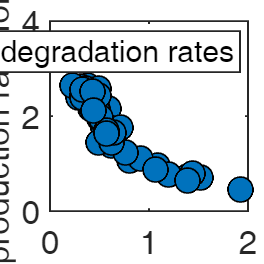

%%% Perturb mRNA degradation

bm=rand(1,60)*5;
a=4000;
b=3;

syms cm

kn_res=zeros(1,length(a));
cm_res=zeros(1,length(a));
for i=1:length(bm)
    vdeg=bm(i)*cm;
    vpro=a/(cm+b);

    eq=vdeg==vpro;
    temp1=solve(eq,cm);
    temp2=double(temp1);
    temp3=temp2(temp2>0);


    cm_res(i)=poissrnd(temp3);%noise
    kn_res(i)=bm(i)*temp3+normrnd(0,(bm(i)*temp3*0.003)^2);%noise

end

%plot (Figure S1f)
colors=["#0072BD"
    "#D95319"
    "#EDB120"
    "#7E2F8E"
    "#77AC30"
    "#4DBEEE"
    "#A2142F"
    '#FF0000'
    '#00FF00'
    '#0000FF'
    '#00FFFF'
    '#FF00FF'
    '#FFFF00'
    '#000000'
    '#FFFFFF'];

fig=figure;
set(fig,'Position',[300 100 700 700]);
ax1=axes('position', [0.19 0.2 0.75 0.72]);

p1=plot(cm_res/80,kn_res/50, ...
    'o', ...
    "MarkerSize",15, ...
    "MarkerEdgeColor",'black',...
    "LineWidth",1,...
    "MarkerFaceColor",colors(1), ...
    "DisplayName",'Perturbe degradation rates');
xlim([0,2])
ylim([0,4])
set(ax1,'LabelFontSizeMultiplier',1.2,'linewidth',1);
set(gca,'FontSize',20)
legend(p1)
ylabel('mRNA production rate fold change','interpreter','tex','FontSize',20);
xlabel('mRNA concentration fold change','interpreter','tex','FontSize',20);